# Time relationships between area,length and dept

## find 90% of Area, Length and Depth

find in [0 135] days, the time that nests arrive to 90% of the max (or final) value for each of the 3 parameters

load('Data\MeanData\MeanBinnedData.mat','S','M','t','varNames')
TMax = table(nan(29,1),nan(29,1),nan(29,1));
TMax.Properties.VariableNames = {'fArea','MaxDepth','fLength'};
t0 = find(t==0); tend = find(t==135);
UseNests =  [2:8 10:13 15:18 20:29];
for k=UseNests
    MaxFArea = max(S(k).B.fArea);
    MaxDepth = max(S(k).B.MaxDepth);
    MaxLength = max(S(k).B.fSkelLength);
    
    TMax.fArea(k) = t(find(S(k).B.fArea>=0.9.*MaxFArea,1,'first'));
    TMax.MaxDepth(k) = t(find(S(k).B.MaxDepth>=0.9.*MaxDepth,1,'first'));
    TMax.fLength(k) = t(find(S(k).B.fSkelLength>=0.9.*MaxLength,1,'first'));
end

## Plot and analyze regressions

% figure
% lm1 = fitlm(TMax,'fLength ~ MaxDepth')
% plot(lm1)

% 
% figure
% lm2 = fitlm(TMax,'fArea ~ fLength')
% plot(lm2)

## Difference in days

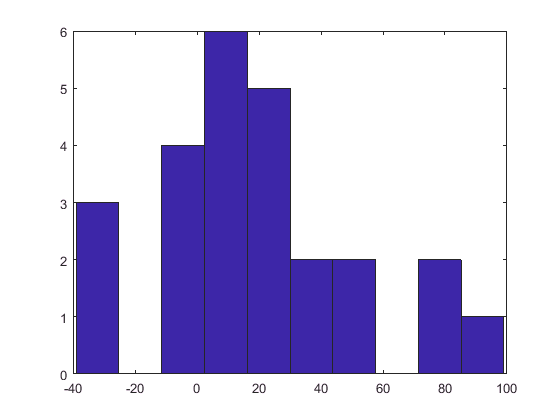

TMax.diffDepthLength = TMax.fLength-TMax.MaxDepth;
figure; hist(TMax.diffDepthLength,10)

MeanLengthAfterDepth = mean(TMax.diffDepthLength,'omitnan')

MeanLengthAfterDepth = 19.3200

SDLengthAfterDepth = std(TMax.diffDepthLength,'omitnan')

SDLengthAfterDepth = 32.4393

SEM = SDLengthAfterDepth./sqrt(numel(UseNests))

SEM = 6.4879

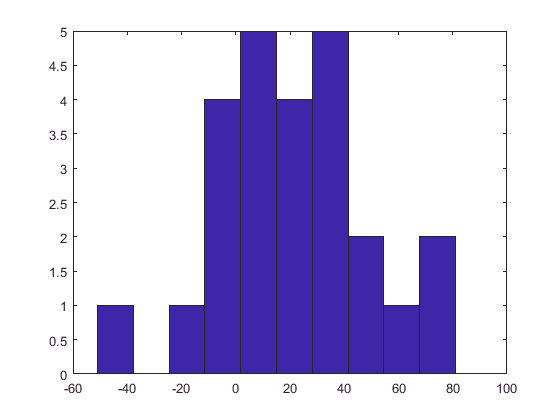


TMax.diffDepthArea = TMax.fArea-TMax.MaxDepth;
figure; hist(TMax.diffDepthArea,10)

MeanAreaAfterDepth = mean(TMax.diffDepthArea,'omitnan')

MeanAreaAfterDepth = 21.2400

SDAreaAfterDepth = std(TMax.diffDepthArea,'omitnan')

SDAreaAfterDepth = 28.5909

SEM = SDAreaAfterDepth./sqrt(numel(UseNests))

SEM = 5.7182

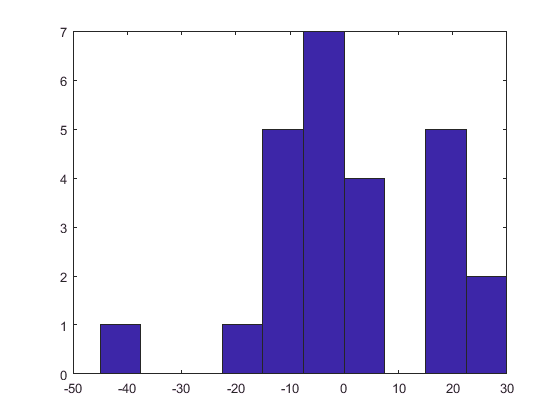


TMax.diffAreaLength = TMax.fArea-TMax.fLength;
figure; hist(TMax.diffAreaLength,10)

MeanAreaAfterLength = mean(TMax.diffAreaLength,'omitnan')

MeanAreaAfterLength = 1.9200

SDAreaAfterLength = std(TMax.diffAreaLength,'omitnan')

SDAreaAfterLength = 16.4973

SEM = SDAreaAfterLength./sqrt(numel(UseNests))

SEM = 3.2995